clc;
clear;
close all;

msym_tb=readcsv("1_MMFFSYMB.csv");
bs_tb=readcsv("6_MMFFBOND.csv");
ab_tb=readcsv("8_MMFFANG.csv");
sb_tb=readcsv("9_MMFFSTBN.csv");
opb_tb=readcsv("11_MMFFOOP.csv");
ti_tb=readcsv("12_MMFFTOR.csv");
vdw_tb=readcsv("13_MMFFVDW.csv");


%% 需要一般化的部分
ori_str="CCC";
nhc=3;
hc=2*nhc+2;
ac=nhc+hc;

%通过一个函数完成H的引入
nh_tb=readtable("CCC_TEST/CCC_NH.csv")

nh_tb = 3×9 table
    Seq    Element    MType    IsAroma    CCount    CHCount    NHBC    CharSym    CharVal
    ___    _______    _____    _______    ______    _______    ____    _______    _______

     0      {'C'}       1         0         1          3        1         0          0   
     1      {'C'}       1         0         2          2        2         0          0   
     2      {'C'}       1         0         1          3        1         0          0   


h_tb=readtable("CCC_TEST/CCC_H.csv")

h_tb = 8×3 table
    Seq    ParentSeq    MType
    ___    _________    _____

     3         0          5  
     4         0          5  
     5         0          5  
     6         1          5  
     7         1          5  
     8         2          5  
     9         2          5  
    10         2          5  


mtype_tb=[nh_tb{:,"MType"};h_tb{:,"MType"}]

mtype_tb =      1
     1
     1
     5
     5
     5
     5
     5
     5
     5




%邻接表
keys={'0','1','2'};
values={[1,3,4,5],[0,2,6,7],[1,8,9,10]};
adj_list=dictionary(keys,values);

%% 构象坐标转换
m4_sphe_tb=readtable("M4.csv")

m4_sphe_tb = 4×4 table
    Seq    R    Theta    Varphi
    ___    _    _____    ______

     0     1       0         0 
     1     1       0     109.5 
     2     1     120     109.5 
     3     1     240     109.5 


m4_rect=[];
for i=1:4
    rect=sphe2rect(m4_sphe_tb{i,"R"},m4_sphe_tb{i,"Theta"},m4_sphe_tb{i,"Varphi"});
    m4_rect=[m4_rect;m4_sphe_tb{i,"Seq"},rect];
end
m4_name=["Seq","X","Y","Z"];
m4_rect_tb=array2table(m4_rect,"VariableNames",m4_name)

m4_rect_tb = 4×4 table
    Seq       X           Y           Z    
    ___    ________    ________    ________

     0            0           0           1
     1      0.94264           0    -0.33381
     2     -0.47132     0.81635    -0.33381
     3     -0.47132    -0.81635    -0.33381


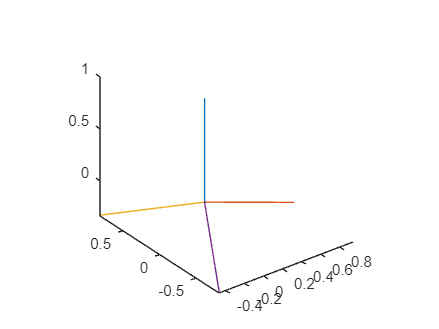


figure;
for i=1:4
    plot3([m4_rect_tb{i,"X"} 0],[m4_rect_tb{i,"Y"} 0],[m4_rect_tb{i,"Z"} 0]);
    hold on;
end
axis equal

%% 初始三维坐标生成
xyz_tb=zeros(nhc+hc,4);

rec_xyz=[1 zeros(1,ac-1)];

max_cname = ["X","Y","Z"];
seq_cname = ["Min","Mid","Max"];
max_xyz = array2table(zeros(2,3), "VariableNames", max_cname);
max_xyz.Properties.RowNames = ["positive","negative"];
max_seq=array2table(max_cname, "VariableNames", seq_cname)

max_seq = 1×3 table
    Min    Mid    Max
    ___    ___    ___

    "X"    "Y"    "Z"


figure;
for i=1:nhc
    now_parent=nh_tb{i,"Seq"};
    m=nh_tb{i,"NHBC"}+nh_tb{i,"CHCount"}
    if m~=4
        disp(m)
        continue
    end
    nb_node=adj_list({num2str(now_parent)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    psize=size(find(nb_node<now_parent),2);
    [vec_ox,vec_oy,vec_oz,B]=deal(0,0,0,0);

    for j=1:nsize
        now_child=nb_node(1,j);

        r0=r0find(bs_tb,mtype_tb,now_parent,now_child);
        if j==1
            %% 第二个原子
            if i==1
                xyz_tb(now_child+1,:)=[now_child,0,0,r0];
                [max_xyz,max_seq]=updatemax_xyz(max_xyz,[0,0,r0]);
                rec_xyz(1,now_child+1)=1;

                line_parent_child(xyz_tb,now_parent,now_child);
                hold on;
            end
            %% 确定坐标系II基矢ox,oy,oz
            [vec_ox,vec_oy,vec_oz]=gencoosys(max_xyz,max_seq,xyz_tb,now_parent,now_child)
            B=genbase(vec_ox,vec_oy,vec_oz);

        elseif now_child>now_parent &&rec_xyz(1,now_child+1)==0
            %% 向量旋转公式
            xyz_j=(r0*B*table2array(m4_rect_tb(j,2:end))')'+xyz_tb(now_parent+1,2:end);
            [max_xyz,max_seq]=updatemax_xyz(max_xyz,xyz_j);
            xyz_tb(now_child+1,:)=[now_child xyz_j];
            rec_xyz(1,now_child+1)=1;

            line_parent_child(xyz_tb,now_parent,now_child);
        end
    end

end

m = 4

vec_ox = 1×3 table
    X    Y    Z
    _    _    _

    1    0    0


vec_oy = 1×3 table
    X    Y    Z
    _    _    _

    0    1    0


vec_oz = 1×3 table
    X    Y    Z
    _    _    _

    0    0    1


m = 4

vec_ox = 1×3 table
    X    Y    Z
    _    _    _

    0    1    0


vec_oy = 1×3 table
    X     Y    Z
    __    _    _

    -1    0    0


vec_oz = 1×3 table
    X    Y    Z 
    _    _    __

    0    0    -1


m = 4

vec_ox = 1×3 table
    X     Y    Z
    __    _    _

    -1    0    0


vec_oy = 1×3 table
    X       Y           Z   
    _    ________    _______

    0    -0.33381    0.94264


vec_oz = 1×3 table
    X       Y           Z    
    _    ________    ________

    0    -0.94264    -0.33381


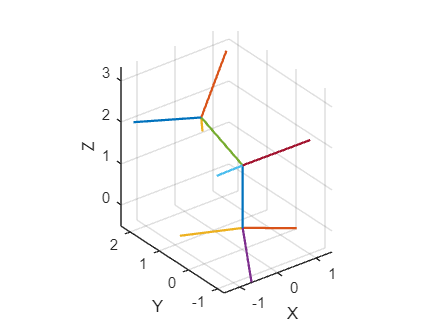

axis equal
grid on
box off
xlabel("X")
ylabel("Y")
zlabel("Z")

xyz_tb

xyz_tb =          0         0         0         0
    1.0000         0         0    1.5080
    2.0000         0    1.4215    2.0114
    3.0000    1.4215         0   -0.5034
    4.0000   -0.7108    1.2311   -0.5034
    5.0000   -0.7108   -1.2311   -0.5034
    6.0000   -1.2311   -0.7108    2.0114
    7.0000    1.2311   -0.7108    2.0114
    8.0000   -1.4215    1.8960    2.1794
    9.0000    0.7108    1.4851    3.3399


%% 总势能计算
sum_eb=0;
sum_ea=0;
sum_eba=0;
sum_eoop=0;
sum_et=0;
sum_evdw=0;

for i=0:nhc-1
    nb_node=adj_list({num2str(i)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);

    %% EB：对第i个原子只遍历编号比i大的相邻节点
    for j=1:nsize


    end

    %% EA：遍历中心原子

    %% EBA：同EA

    %% EOOP：仅AllBond=3时，同EA

    %% ET：同EB

    %% EVDW：BFS

end

function tb=readcsv(csv_filename)
csv_folder = "../Values/MMFF94_CSV";
tb = readtable(fullfile(csv_folder,csv_filename));
end

function rect=sphe2rect(r,theta,varphi)
x=r*sind(varphi)*cosd(theta);
y=r*sind(varphi)*sind(theta);
z=r*cosd(varphi);
rect=[x,y,z];
end

function r0=r0find(r0_tb,mtype_tb,seq_i,seq_j)
mtype_i=mtype_tb(seq_i+1,1);
mtype_j=mtype_tb(seq_j+1,1);
for i=1:size(r0_tb,1)
    if r0_tb{i,"MTYPE_I"}==mtype_i&& r0_tb{i,"MTYPE_J"}==mtype_j || r0_tb{i,"MTYPE_I"}==mtype_j&& r0_tb{i,"MTYPE_J"}==mtype_i
        r0=r0_tb{i,"R0"};
    end
end
row=matchmtype(["R0"],r0_tb,[mtype_i,mtype_j],["MTYPE_I","MTYPE_J"],"No");
r0=row{1,"R0"};
end

function [new_xyz,new_seq]=updatemax_xyz(old_xyz,dot_xyz)
new_xyz=old_xyz;
for i=1:3
    rowname="positive";
    if dot_xyz(1,i)<0
        rowname="negative";
    end
    if abs(old_xyz{rowname,i})<abs(dot_xyz(1,i))
        new_xyz{rowname,i}=dot_xyz(1,i);
    end
end
sin_new_xyz=max(abs(table2array(new_xyz)));

[~,maxi]=max(sin_new_xyz);
[~,mini]=min(sin_new_xyz);

midi=6-maxi-mini;

mch = ["X","Y","Z"];
seq_cname = ["Min","Mid","Max"];
new_seq =array2table([mch(1,mini),mch(1,midi),mch(1,maxi)], "VariableNames", seq_cname);
end

function vec_xyz=genvec_xyz(arr_xyz)
vec_xyz=array2table(arr_xyz, "VariableNames",["X","Y","Z"]);
end

function result=cdotvec(vec1,vec2)
result=0;
for i=1:size(vec1,2)
    result=result+vec1{1,i}*vec2{1,i};
end
end

function new_vec=normvec(vec)
mid_vec=table2array(vec);
new_vec=array2table(mid_vec/norm(mid_vec),"VariableNames",["X","Y","Z"]);
end

function [vec_ox,vec_oy,vec_oz]=gencoosys(max_xyz,max_seq,xyz_tb,now_parent,now_child)
% 求解oz
vec_oz=xyz_tb(now_child+1,2:end)-xyz_tb(now_parent+1,2:end);
vec_oz=genvec_xyz(vec_oz/norm(vec_oz));

%求解ox
vec_ox=genvec_xyz(zeros(1,3));
kx=1;
if max_xyz{"positive",max_seq{1,"Min"}}+max_xyz{"negative",max_seq{1,"Min"}}>0
    kx=-1;
end
vec_ox{1,max_seq{1,"Max"}}=0;
vec_ox{1,max_seq{1,"Min"}}=kx;
c_xz=cdotvec(vec_ox,vec_oz);
if c_xz~=0
    vec_ox{1,max_seq{1,"Mid"}}=c_xz/vec_oz{1,max_seq{1,"Mid"}};
end
vec_ox=normvec(vec_ox);
%% 求解oy
vec_oy=genvec_xyz(zeros(1,3));
ky=1;
if max_xyz{"positive",max_seq{1,"Mid"}}+max_xyz{"negative",max_seq{1,"Mid"}}>0
    ky=-1;
end
vec_oy{1,max_seq{1,"Mid"}}=ky;
A=[vec_ox{1,max_seq{1,"Max"}},vec_ox{1,max_seq{1,"Min"}};
    vec_oz{1,max_seq{1,"Max"}},vec_oz{1,max_seq{1,"Min"}}];
b=[-vec_ox{1,max_seq{1,"Mid"}}*ky;-vec_oz{1,max_seq{1,"Mid"}}*ky];
result=(A\b)';
vec_oy{1,max_seq{1,"Max"}}=result(1,1);
vec_oy{1,max_seq{1,"Min"}}=result(1,2);
vec_oy=normvec(vec_oy);
end

function B=genbase(ox,oy,oz)
B=[table2array(ox)' table2array(oy)' table2array(oz)';];
end
function p=line_parent_child(xyz_tb,parent,child)
p=plot3([xyz_tb(child+1,2),xyz_tb(parent+1,2)], ...
    [xyz_tb(child+1,3),xyz_tb(parent+1,3)], ...
    [xyz_tb(child+1,4),xyz_tb(parent+1,4)],"-",LineWidth=1.5);
end

function EB=getEB(r_ij,bs_tb,mtype_arr)
row=matchmtype(["R0","KB"],bs_tb,mtype_arr,["MTYPE_I","MTYPE_J"],"No");
kb=row{1,"R0"};
r0=row{1,"KB"};
delta_r=r_ij-r0;
cs=-2;
EB=143.9525*kb/2*delta_r*(1+cs*delta_r+7/12*cs^2*delta_r^2);
end

function EA=getEA(var_ij,ab_tb,mtype_arr)
row=matchmtype(["THETA_0","KA_IJK"],ab_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
ka=row{1,"KA_IJK"};
var0=row{1,"THETA_0"};

cb=deg2rad(-0.007);
dvar=deg2rad(var_ij-var0);

EA=0.043844*ka/2*dvar^2*(1+cb*dvar);
end

function EBA=getEBA(var_ij,r_ij,r_kj,sb_tb,bs_tb,ab_tb,mtype_arr)
row_ijk_1=matchmtype(["KBA_KJI","KBA_IJK"],sb_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
kba_ijk=row_ijk_1{1,"KBA_IJK"};
kba_kji=row_ijk_1{1,"KBA_KJI"};

row_ij=matchmtype("R0",bs_tb,mtype_arr(:,1:2),["MTYPE_I","MTYPE_J"],"No");
r0_ij=row_ij{1,"R0"};

row_kj=matchmtype("R0",bs_tb,mtype_arr(:,2:3),["MTYPE_I","MTYPE_J"],"No");
r0_kj=row_kj{1,"R0"};

row_ijk_2=matchmtype("THETA_0",ab_tb,atype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
var0=row_ijk_2{1,"THETA_0"};

dr_ij=r_ij-r0_ij;
dr_kj=r_kj-r0_kj;
dvar=deg2rad(var_ij-var0);

EBA=2.51210*(kba_ijk*dr_ij+kba_kji*dr_kj)*dvar;
end

function EOOP=getEOOP(chi_ijkl,opb_tb,mtype_arr)
row=matchmtype("KOOP",opb_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K","MTYPE_L"],"Yes");
koop=row{1,"KOOP"};
EOOP=0.034844*koop/2*chi_ijkl^2;
end

function ET=getET(phi,ti_tb,mtype_arr)
row=matchmtype(["V1","V2","V3"],ti_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K","MTYPE_L"],"No");
V1=row{1,"V1"};
V2=row{1,"V2"};
V3=row{1,"V3"};

ET=0.5*(V1*(1+cosd(phi))+V2*(1-cosd(2*phi)+V3*(1+cosd(3*phi))));
end

function EVDW=getEVDW(R_ij,vdw_tb,mtype_arr)
row_i=matchmtype(["N_I","A_I","G_I","ALPHA_I"],vdw_tb,[mtype_arr(1,1)],["MTYPE_I"],"No");
row_j=matchmtype(["N_I","A_I","G_I","ALPHA_I"],vdw_tb,[mtype_arr(1,2)],["MTYPE_I"],"No");
A_i=row_i{1,"A_I"};
A_j=row_j{1,"A_I"};
G_i=row_i{1,"G_I"};
G_j=row_j{1,"G_I"};
N_i=row_i{1,"N_I"};
N_j=row_j{1,"N_I"};
alpha_i=row_i{1,"ALPHA_I"};
alpha_j=row_j{1,"ALPHA_I"};

B=0.2;
beta=12;

Rv_ii=A_i*alpha_i^0.25;
Rv_jj=A_j*alpha_j^0.25;
gamma_ij=(Rv_ii-Rv_jj)/(Rv_ii+Rv_jj);
Rv_ij=0.5*(Rv_ii+Rv_jj)*(1+B*(1-exp(-beta*gamma_ij^2)));
epsilon_ij=181.16*G_i*G_j*alpha_i*alpha_j/((alpha_i/N_i)^0.5+(alpha_j/N_j)^0.5)/Rv_ij^6;

EVDW=epsilon_ij*(1.07*Rv_ij/(R_ij+0.07*Rv_ij))^7*(1.12*Rv_ij^7/(R_ij+0.12*Rv_ij^7)-2);

end

function row=matchmtype(des_ch,tb,mtype_arr,mtype_ch,bycenter_j)
dsize=size(des_ch,2);
row=array2table(zeros(1,dsize),"VariableNames",des_ch);

for i=1:size(tb,1)
    rm=tb{i,mtype_ch};
    judge=false;
    if bycenter_j~="Yes"
        rm_f=fliplr(rm);
        judge=isequal(rm,mtype_arr) || isequal(rm_f,mtype_arr);
    else
        if mtype_arr(1,2)==rm(1,2)
            ams=sort(mtype_arr);
            rms=sort(rm);
            if isequal(type,rm)
                judge=true;
            end
        end
    end
    
    if judge
        for j=size(des_ch,2)
            row{1,des_ch(1,j)}=tb{1,des_ch(1,j)};
        end
        break
    end
end

end